# sExample: COVID-2019 data for Hubei, China

I am taking some data from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

**Important notice:**

The fitting is here more challenging than in Example 1 because the term "Confirmed patient" used in the database does not precise whether they have been quarantined or not. In the following, it is assumed that every person found positive to the virus is automatically placed in quarantine. Note: In a previous version of the submision (version <1.5) , the infectious cases were erroneously used instead of the quarantined cases. 

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
% time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 29-Apr-2020


Location = 'Hubei';
try
    indR = find(contains(tableRecovered.ProvinceState,Location)==1);
    indC = find(contains(tableConfirmed.ProvinceState,Location)==1);
    indD = find(contains(tableDeaths.ProvinceState,Location)==1);
catch exception
    searchLoc = strfind(tableRecovered.ProvinceState,Location);
    indR = find(~cellfun(@isempty,searchLoc)) ; 
    
    searchLoc = strfind(tableConfirmed.ProvinceState,Location);
    indC = find(~cellfun(@isempty,searchLoc))  ;
    
    searchLoc = strfind(tableDeaths.ProvinceState,Location);
    indD = find(~cellfun(@isempty,searchLoc))   ; 
end

disp(tableRecovered(indR,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

       "Hubei"          "China"   



disp(tableConfirmed(indC,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

       "Hubei"          "China"   



disp(tableDeaths(indD,1:2))

    ProvinceState    CountryRegion
    _____________    _____________

       "Hubei"          "China"   




indR = indR(1);
indD = indD(1);
indC = indC(1);

Recovered = table2array(tableRecovered(indR,5:end));
Deaths = table2array(tableDeaths(indD,5:end));
Confirmed = table2array(tableConfirmed(indC,5:end));
% If the number of confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
minNum= round(0.1*max(Confirmed));

indRemoved = unique([find(Confirmed<=minNum),find(isnan(Confirmed))]);
Recovered(indRemoved)=[];
Deaths(indRemoved)=[];
time(indRemoved)= [];
Confirmed(indRemoved)=[];

if isempty(Confirmed)
    warning('"Confirmed" is an empty array. Check the value of "minNum". Computation aborted.')
    return
end


Npop= 14e6; % population

## Fitting of the generalized SEIR model to the real data

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 0.9; % Infection rate
LT_guess = 5; % latent time in days
Q_guess = 0.1; % rate at which infectious people enter in quarantine
lambda_guess = [0.1,0.5,0.1]; % recovery rate
kappa_guess = [0.08,0.03]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    Q_guess,...
    lambda_guess,...
    kappa_guess];


% Initial conditions
E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1)-Recovered(1)-Deaths(1);
R0 = Recovered(1);
D0 = Deaths(1);

% Active cases
Active = Confirmed-Recovered-Deaths;
Active(Active<0) = 0; % No negative number possible
% Parameter estimation with the lsqcurvefit function
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,lambdaFun] = ...
    fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess,'Display','off');

## Simulate the epidemy outbreak based on the fitted parameters

dt = 1/24; % time step
time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(10)));
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t,lambdaFun);

## Comparison of the fitted and real data

Active cases = Confirmed-Deaths-Recovered (database) = Quarantined (SEIQRDP model)

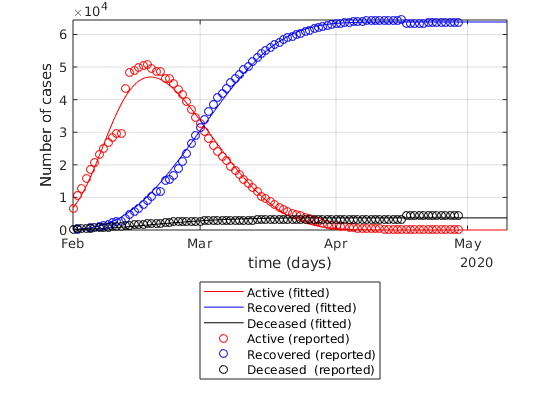

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Active,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Active (fitted)',...
        'Recovered (fitted)','Deceased (fitted)',...
        'Active (reported)','Recovered (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
set(gca,'yscale','lin')